# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

## 实验四 离散傅里叶级数及其变换

## 一、实验目的

- 加深对离散周期序列傅里叶级数(DFS)基本概念的理解

- 掌握MATLAB求解周期序列傅里叶级数变换和逆变换的方法

- 加深对离散傅里叶变换(DFT)基本概念的理解

- 掌握MATLAB进行离散傅里叶变换和逆变换的方法

- 了解有限长序列傅里叶变换(DFT)性质的研究方法

- 掌握MATLAB进行离散傅里叶变换性质分析时程序编写的方法

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

## **        1.周期序列的离散傅里叶级数：**

            离散时间序列x(n)满足$x{\left(n\right)}=x\left(n+rN\right)$，称为离散周期序列，用表示。其中，N为信号的周期，x(n)称为离散周期序列的主值。周期序列$\overset{~}{x} \left(n\right)$可以用离散傅里叶级数(DFS)表示：


$$\overset{~}{x} {\left(n\right)}=\frac{1}{N}\sum_{k=0}^{N-1} \overset{~}{X} {\left(k\right)}e^{j\frac{2\pi }{N}kn} =IDFS{\left[\overset{~}{X} {\left(k\right)}\right]}\ \ \ \ \ \ \ n=0,1,\dots ,N-1$$


            其中，$\overset{~}{X} \left(k\right)$是周期序列离散傅里叶级数第k次谐波分量的系数，也称为周期序列的频谱，可表示为：


$$\overset{~}{X} {\left(k\right)}=\sum_{n=0}^{N-1} \overset{~}{x} {\left(n\right)}e^{-j\frac{2\pi }{N}kn} =DFS{\left[\overset{~}{x} {\left(n\right)}\right]}\ \ \ \ \ \ k=0,1,\dots ,N-1$$


            由上面两式可以看出，它们也是周期序列的一对傅里叶级数变换对。

            令$W_N =e^{-j\frac{2\pi }{N}}$，以上傅里叶级数变换对又可以写成：


$$\overset{~}{X} {\left(k\right)}=DFS{\left[\overset{~}{x} {\left(n\right)}\right]}=\sum_{n=0}^{N-1} \overset{~}{x} {\left(n\right)}W_N^{nk} \ \ \ \ \ \ k=0,1,\dots ,N-1$$



$$\overset{~}{x} {\left(n\right)}=IDFS{\left[\overset{~}{X} {\left(k\right)}\right]}=\frac{1}{N}\sum_{k=0}^{N-1} \overset{~}{X} {\left(k\right)}W_N^{-nk} \ \ \ \ \ \ n=0,1,\dots ,N-1$$


            与连续性周期信号的傅里叶级数相比较，周期序列离散傅里叶级数有着如下特点:

            (1)连续性周期信号的傅里叶级数对应的第k次谐波分量的系数为无穷多。而周期为N的周期序列,其离散傅里叶级数谐波分量的系数只有N个是独立的。

            (2)周期序列的频谱X(k)也是一个以N为周期的周期序列。

## **        2.**周期序列的卷积和**：**

            时域周期序列的卷积和与频域周期序列的积相互对应。若$\overset{~}{Y} {\left(k\right)}=\overset{~}{X_1 } \left(k\right)\textrm{∙}\overset{~}{X_2 } \left(k\right)$，则

 
$$\overset{~}{y} {\left(n\right)}=IDFS{\left[\overset{~}{Y} {\left(k\right)}\right]}$$

$$=\sum_{m=0}^{N-1} \overset{~}{x_1 } {\left(m\right)}\overset{~}{x_2 } {\left(n-m\right)}=\sum_{m=0}^{N-1} \overset{~}{x_2 } {\left(m\right)}\overset{~}{x_1 } \left(n-m\right)$$

$$=\overset{~}{x_1 } {\left(n\right)}*\overset{~}{x_2 } \left(n\right)$$


            注意:周期序列的卷积和与非周期序列的卷积和有所区别。

            (1)$\overset{~}{{\ \ \ x}_1 } \left(m\right)$和$\overset{~}{x_2 } \left(n-m\right)$均为变量为m，周期为N的周期序列,故它们的乘积也是周期序列。

            (2)卷积求和是在一个周期内进行的，即从m=0到 m=N-1。

            (3)如果$x_1 \left(n\right)$和$x_2 \left(n\right)$的周期长度不同，则卷积和的长度取N=max[N1,N2]。

## **        3.**有限长序列的傅里叶变换（DFT)和逆变换（IDFT)**：**

            在实际中常常使用有限长序列。如果有限长序列信号为x(n)，则该序列的离散傅里叶变换对可以表示为：


$$X{\left(k\right)}=DFT{\left[x{\left(n\right)}\right]}=\sum_{n=0}^{N-1} x\left(n\right)W_N^{nk} \ \ \ k=0,1,\dots N-1$$



$$x{\left(n\right)}=IDFT{\left[X{\left(k\right)}\right]}=\frac{1}{N}\sum_{k=0}^{N-1} X{\left(k\right)}W_N^{-nk} \ \ \ \ n=0,1,\dots ,N-1$$


            从离散傅里叶变换定义式可以看出,有限长序列在时域上是离散的,在频域上也是离散的。式中$W_N =e^{-j\frac{2\pi }{N}}$，即仅在单位圆上N个等间距的点上取值，这为使用计算机进行处理带来了方便。

            由有限长序列的傅里叶变换和逆变换定义可知,DFT 和 DFS的公式非常相似,因此在程序编写上也基本一致。

##         4. 有限长序列 DFT与周期序列DFS的联系：

            将周期序列的傅里叶级数变换对与有限长序列离散傅里叶变换对进行比较，可以看出两者的区别仅仅是将周期序列$\overset{~}{x} \left(n\right)$换成了有限长序列x(n)。同时，由于式中的$W_N^{nk}$的周期性,因而有限长序列的离散傅实际上隐含着周期性。

##         5. 有限长序列 DFT与离散时间傅里叶变换 DTFT的联系

            离散时间傅里叶变换(DTFT)是指信号在时域上为离散的，而在频域上则是连续的。

            如果离散时间非周期信号为x(n）,则它的离散傅里叶变换对(DTFT)表示为：


$$DTFT{\left[x{\left(n\right)}\right]}=X{\left(e^{jw} \right)}=\sum_{n=0}^{\infty } x\left(n\right)e^{-jwn}$$



$$IDTFT{\left[X{\left(e^{jw} \right)}\right]}=x{\left(n\right)}=\frac{1}{2\pi }\int_{-\pi }^{\pi } X\left(e^{jw} \right)e^{jwn} dw$$


            其中$X\left(e^{jw} \right)$称为信号序列的频谱。将频谱表示为：


$$X{\left(e^{jw} \right)}=\left|X{\left(e^{jw} \right)}\left|e^{j\varphi \left(w\right)} \right.$$


            $\left|X{\left(e^{jw} \right)}\left|\right.$称为序列的幅度谱，$\varphi {\left(w\right)}=\mathrm{a}\mathrm{r}\mathrm{g}\left|X{\left(e^{jw} \right)}\left|\right.$称为序列的相位谱。

            从离散时间傅里叶变换的定义可以看出,信号在时域上是离散的、非周期的,而在频域上则是连续的、周期性的。

            与有限长序列相比,$X\left(e^{jw} \right)$仅在单位圆上取值,X(k)是在单位圆上N个等间距的点上取值。因此,连续谱$X\left(e^{jw} \right)$可以由离散谱X(k)经插值后得到。

## 四、实验所用MATLAB函数

- angle函数： 求相角

- grid函数： 在指定的图形坐标上绘制分格线

- length函数：求序列长度

- mod函数：求余数

## 五、实验内容、方法、代码与结果

### **题目1**：已知一个信号序列的主值为$x\left(n\right)=\left\lbrack 1,2,3,4,3,2,1\right\rbrack$，显示2个周期的信号序列波形。要求：

**①用傅里叶级数变换求信号的幅度频谱和相位频谱，用图形表示**`；`

**②**`求傅里叶级数逆变换的图形，并与原信号图形进行比较。`

**解答1**：

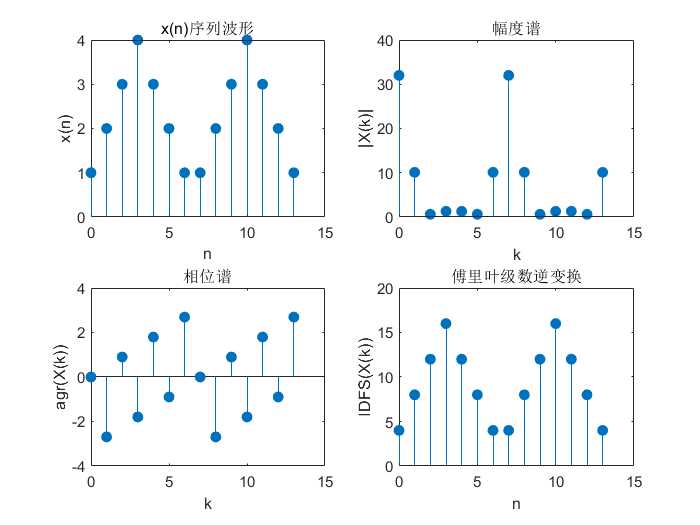

clc;
clear;
figure();
x=[1,2,3,4,3,2,1];
N=length(x);
xn=[x,x];
n=0:2*N-1;
k=0:2*N-1;
subplot(2,2,1);
stem(n,xn,'filled');
xlabel('n');
ylabel('x(n)');
title('x(n)序列波形');

subplot(2,2,2);
Xk=xn*exp(-1j*2*pi/N).^(n'*k);%离散傅里叶级数变换
stem(k,abs(Xk),'filled');
title('幅度谱')%幅度谱
xlabel('k');
ylabel('|X(k)|');

subplot(2,2,3);
stem(k,angle(Xk),'filled');
title('相位谱')%相位谱
xlabel('k');
ylabel('agr(X(k))');

subplot(2,2,4);
x=(Xk*exp(1j*2*pi/N).^(n'*k))/N;%逆变换
stem(n,abs(x),'filled');
title('傅里叶级数逆变换')%显示逆变换结果
xlabel('n');
ylabel('IDFS(X(k))');

### **题目2**：已知有限长序列$x\left(n\right)=\left\lbrack 7,5,6,4,3,2\right\rbrack$，求$x\left(n\right)$的DFT和IDFT。要求：

**①画出序列傅里叶变换对应的**$\left|X\left(k\right)\right|$和$\arg \left\lbrack X\left(k\right)\right\rbrack$的图形`；`

**②画出原信号与傅里叶逆变换IDFT**$\left\lbrack X\left(k\right)\right\rbrack$的图形进行比较`。`

**解答2**：

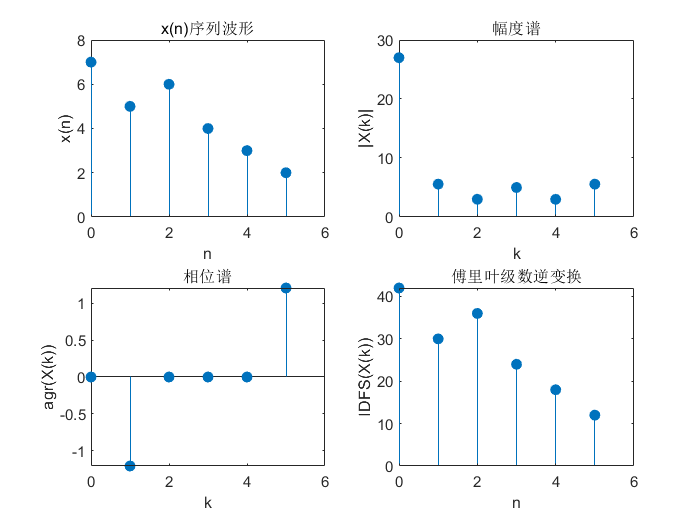

clc;
clear;
figure();
xn=[7,5,6,4,3,2];
N=length(xn);
n=0:N-1;
k=0:N-1;
Xk=xn*exp(-1j*2*pi/N).^(n'*k);%离散傅里叶变换
x=(Xk*exp(1j*2*pi/N).^(n'*k));%离散傅里叶逆变换
subplot(2,2,1);
stem(n,xn,'filled');
xlabel('n');
ylabel('x(n)');
title('x(n)序列波形');

subplot(2,2,2);
stem(k,abs(Xk),'filled');
title('幅度谱')%幅度谱
xlabel('k');
ylabel('|X(k)|');

subplot(2,2,3);
stem(k,angle(Xk),'filled');
title('arg[X(k)]');
title('相位谱')%相位谱
xlabel('k');
ylabel('agr(X(k))');

subplot(2,2,4);
stem(n,abs(x),'filled');title('arg[X(k)]');
title('傅里叶级数逆变换')%显示逆变换结果
xlabel('n');
ylabel('IDFS(X(k))');

### **题目3**：已知周期序列的主值$x\left(n\right)=\left\lbrack 7,6,5,3,4,2\right\rbrack$,求$x\left(n\right)$周期重复次数为3次时的DFS和IDFS。要求：

**①画出原信号序列的主值和周期序列的图形**`；`

**②画出序列傅里叶变换对应的**$\left|\tilde{X} \left(k\right)\right|$和$\arg \left\lbrack \tilde{X} \left(k\right)\right\rbrack$的图形`。`

**解答3**：

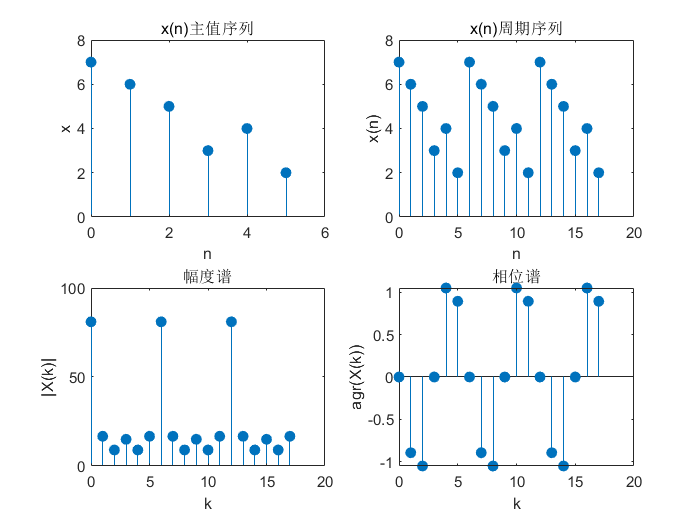

clc;
clear;
figure();
x=[7,6,5,3,4,2];
N=length(x);
xn=[x,x,x];
n=0:3*N-1;
k=0:3*N-1;
subplot(2,2,1);
stem(0:N-1,x,'filled');
xlabel('n');
ylabel('x');
title('x(n)主值序列');

subplot(2,2,2);
stem(n,xn,'filled');
xlabel('n');
ylabel('x(n)');
title('x(n)周期序列');

subplot(2,2,3);
Xk=xn*exp(-1j*2*pi/N).^(n'*k);%离散傅里叶级数变换
stem(k,abs(Xk),'filled');
title('幅度谱')%幅度谱
xlabel('k');
ylabel('|X(k)|');

subplot(2,2,4);
stem(k,angle(Xk),'filled');
title('相位谱')%相位谱
xlabel('k');
ylabel('agr(X(k))');

### **题目4**：求$x\left(n\right)=\left\lbrack 7,6,5,4,3,2\right\rbrack ,0\le n\le 5$的DTFT，将$\left(-2\pi ,2\pi \right)$区间分成200份。要求：

**①画出原信号**`；`

**②画出序列傅里叶变换对应的**$X(e^{j\omega})$和$arg[X(e^{j\omega})]$的图形`。`

**③求有限长序列**$x\left(n\right)=\left\lbrack 7,6,5,4,3,2\right\rbrack ,N=100$时的DFT，并与DTFT的结果进行比较`；`

**解答4**：

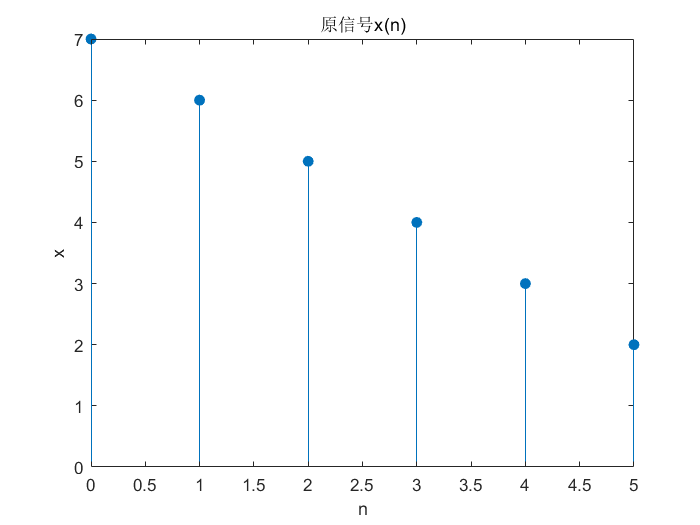

clc;
clear;
figure();
xn=[7,6,5,4,3,2];
N=length(xn);
n=0:N-1;

stem(n,xn,'filled');
title('原信号x(n)');
xlabel('n');
ylabel('x');

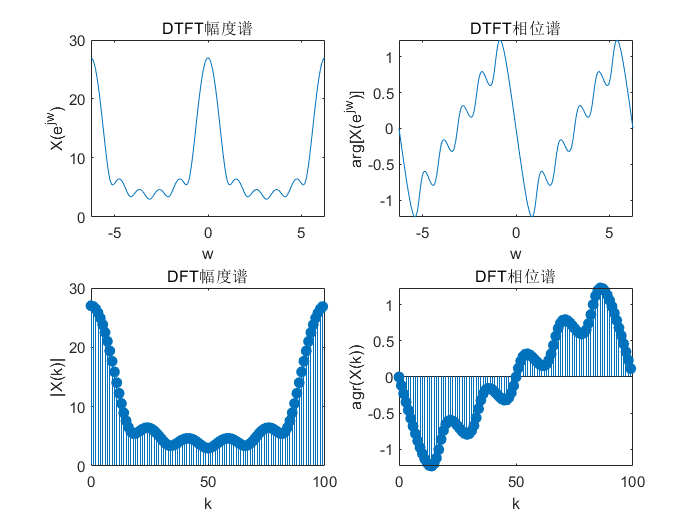


figure();
w=linspace(-2*pi,2*pi,200);%将区间分成200份
Xw=xn*exp(-1j*n'*w);
subplot(2,2,1);
plot(w,abs(Xw));
title('DTFT幅度谱');
xlabel('w');
ylabel('X(e^{jw})');

subplot(2,2,2);
plot(w,angle(Xw));
title('DTFT相位谱');
xlabel('w');
ylabel('arg[X(e^{jw})]');

Nz=100;
xn_=[7,6,5,4,3,2,zeros(1,Nz-N)];
n=0:Nz-1;
k=0:Nz-1;
Xk=xn_*exp(-1j*2*pi/Nz).^(n'*k);%离散傅里叶变换
subplot(2,2,3);
stem(k,abs(Xk),'filled');
title('DFT幅度谱');%幅度谱
xlabel('k');
ylabel('|X(k)|');

subplot(2,2,4);
stem(k,angle(Xk),'filled');
title('DFT相位谱')%相位谱
xlabel('k');
ylabel('agr(X(k))');

### **题目5**：已知一个有限长信号序列$x\left(n\right)=\left\lbrack 8,7,6,5,4,3,2,1\right\rbrack$，循环长度取N=10。求证：在时域循环折叠后的函数$x\left(-n\right)$，其对应的DFT在频域也作循环折叠，作图示意（提示：循环折叠前后DFT的实部画在同一幅子图内，虚部同理，即实部、虚部各画一张子图）。

**解答5**：

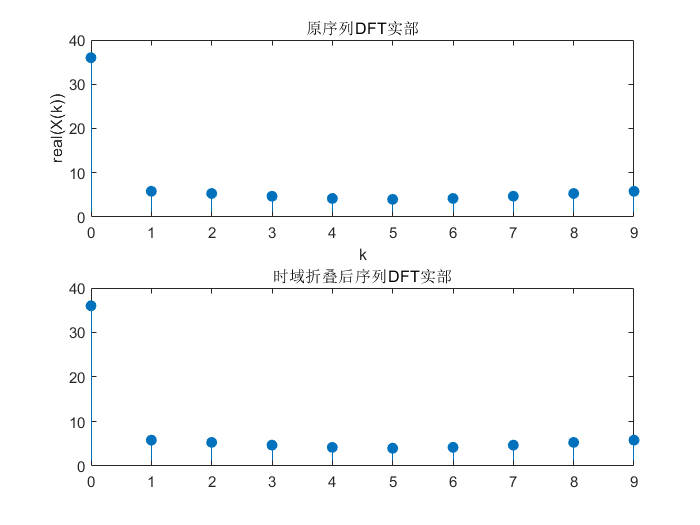

clc;
clear;
figure();
xn=[8,7,6,5,4,3,2,1];
Ln=length(xn);
N=10;%循环长度
xn_con=[xn,zeros(1,N-Ln)];
n=0:9;
k=0:9;
Xk=xn_con*exp(-1j*2*pi/N).^(n'*k);%离散傅里叶变换
yn_con=xn_con(mod(-n,10)+1);
Yk=yn_con*exp(-1j*2*pi/N).^(n'*k);%离散傅里叶变换

subplot(2,1,1);
stem(k,real(Xk),'filled');
title('原序列DFT实部');
xlabel('k');
ylabel('real(X(k))');

subplot(2,1,2);
stem(k,real(Yk),'filled');
title('时域折叠后序列DFT实部');

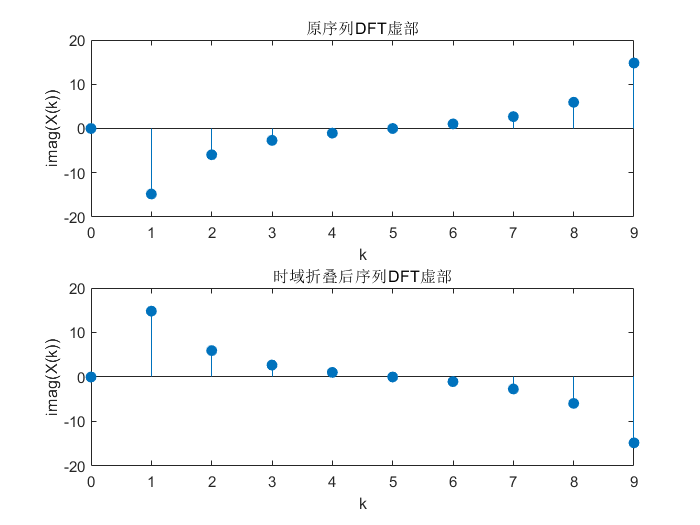


figure();
subplot(2,1,1);
stem(n,imag(Xk),'filled');
title('原序列DFT虚部');
xlabel('k');
ylabel('imag(X(k))');

subplot(2,1,2);
stem(k,imag(Yk),'filled');
title('时域折叠后序列DFT虚部');
xlabel('k');
ylabel('imag(X(k))');

%实序列的离散傅里叶变换满足共轭对称，即X(k)=X*(N-k)
%观察图像可得DFT[x(-n)]=X*(k)
%由X(k)=X*(N-k)得DFT[x(-n)]=X*(k)=X（N-k)
%因此时域循环折叠后的X(-n)DFT在频域循环折叠
%得证